# Summer School

## Reset

clear;              % clear all the workspace
clc;                % clear all the command window
addpath 'D:\Users\Y.H.Tian\Desktop\学习\UOG\Msc Project\code\Tian\SER_Library_Tian'

## Read Dataset

- create a index (datastore) for the database

audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/SAVEE_16000';           % get the path of audios in the chosen database
audio_ds = audioDatastore(audio_data_path,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)
audio_number = length(audio_ds.Files);                  % get how many audio files in the datastore
reset(audio_ds);                                        % reset(ds) resets the datastore specified by ds to the state where no data has been read from it. 

## Create a datastore with specific types (happy + anger + neutral)

- try by using my function "creat_datastore_fit_type"

type_happy_ds = creat_datastore_fit_type(audio_ds,2,'h',nan,nan,nan,nan,nan,nan,nan,nan,nan);   % try happy (h)
type_anger_ds = creat_datastore_fit_type(audio_ds,2,'a',nan,nan,nan,nan,nan,nan,nan,nan,nan);     % try anger (a)
type_neutral_ds = creat_datastore_fit_type(audio_ds,2,'n',nan,nan,nan,nan,nan,nan,nan,nan,nan);   % try neutral (n)

- combine datastore

% Reset (clear) the folder for storing the audio agree with specific type
destination_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/COMBINED';
cd '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/COMBINED'
delete *.wav
cd '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/Tian/'

% then copy all specific audio to that folder
% in this case, happy and sad audio in EMODB
for i=1:length(type_happy_ds.Files)  
    copyfile(type_happy_ds.Files{i},destination_path);
end

for i=1:length(type_anger_ds.Files)  
    copyfile(type_anger_ds.Files{i},destination_path);
end

for i=1:length(type_neutral_ds.Files)  
    copyfile(type_neutral_ds.Files{i},destination_path);
end

% create a new datastore 
audio_type_ds = audioDatastore(destination_path,'FileExtensions','.wav');                             
audio_type_number = length(audio_type_ds.Files);                
reset(audio_type_ds);

% put emotion labels on it
audio_type_ds = put_emotion_labels(audio_type_ds);

- Split datastore for test and train (25% for test)

[audio_type_ds_train, audio_type_ds_test] = splitEachLabel(audio_type_ds,0.75);

## Train the model

fs = 16000;
MFCC_Coe = 13;
frame_length_sec = 0.1;         % 0.1 sec frame
overlap_percentage = 0.5;        % 50% overlap
[mdl] = MFCC_KNN(audio_type_ds_train,fs,MFCC_Coe,frame_length_sec,overlap_percentage);

## Test the model

- get the features of the test data

                            Settings

aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                    
    "Window",hamming(round(frame_length_sec*fs),"periodic"), ...
    "OverlapLength",round(frame_length_sec*(1-overlap_percentage)*fs), ...
    "mfcc",true ...                          % require MFCC as features
    );
setExtractorParams(aFE,"mfcc","NumCoeffs",MFCC_Coe);    % set MFCC coe numbers
feature_label = creat_feature_label(aFE);               % create a label for what features did we chose

                            Feature extraction 

audio_type_ds_test = transform(audio_type_ds_test,@(audio_in, info_in) feature_extraction_voicing(audio_in, info_in, aFE), "IncludeInfo",true);           % automatic feature extraction
feature_test = readall(audio_type_ds_test);   

                            put feature labels on the result table from the previous step (For easy observation)

feature_test = cell2table(feature_test);
feature_test.Properties.VariableNames = feature_label;
feature_test.Emotion = categorical(feature_test.Emotion);

                            Normalization

Normalize_features = table2array(feature_test(:,1:end-1));
m = mean(Normalize_features);
s = std(Normalize_features);
Normalize_features = (Normalize_features-m)./s;
feature_test(:,1:end-1) = array2table(Normalize_features);


- Test

inputTable = feature_test;
predictors = inputTable(:, 1:end-1);
validationResponse = inputTable.Emotion;

[validationPredictions, validationScores] = predict(mdl, predictors);

correctPredictions = (validationPredictions == validationResponse);
isMissing = ismissing(validationResponse);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

- Draw the confusion Matrix

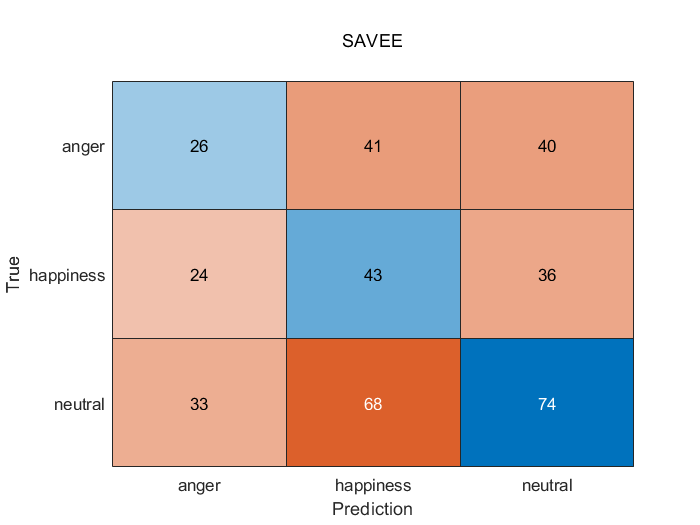

figure(1);
confusion_matrix1 = confusionchart(validationResponse,validationPredictions);
confusion_matrix1.Title = {'';'SAVEE';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';

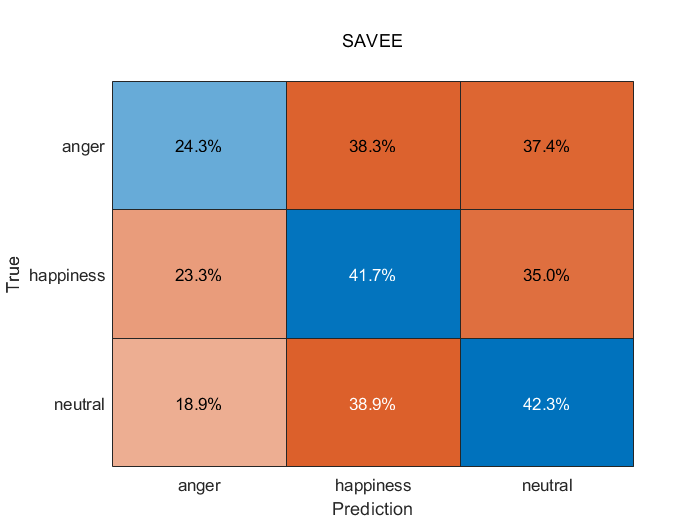


figure(2);
confusion_matrix2 = confusionchart(validationResponse,validationPredictions);
confusion_matrix2.Title = {'';'SAVEE';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';